# Lab 6: MNIST Digit Classification with kNN and SVMs

## Dataset

In this lab, we will be using the MNIST Dataset, which can be downloaded from [http://yann.lecun.com/exdb/mnist/.](http://yann.lecun.com/exdb/mnist)

The MNIST Dataset is a set of black and white photos of handwritten digits with their corresponding labels from 0 to 9. 

 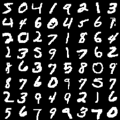

There are four files on this website - 

[`train-images-idx3-ubyte.gz`](http://yann.lecun.com/exdb/mnist/train-images-idx3-ubyte.gz)`:  training set images (9912422 bytes)` 

[`train-labels-idx1-ubyte.gz`](http://yann.lecun.com/exdb/mnist/train-labels-idx1-ubyte.gz)`:  training set labels (28881 bytes)` 

[`t10k-images-idx3-ubyte.gz`](http://yann.lecun.com/exdb/mnist/t10k-images-idx3-ubyte.gz)`:   test set images (1648877 bytes)` 

[`t10k-labels-idx1-ubyte.gz`](http://yann.lecun.com/exdb/mnist/t10k-labels-idx1-ubyte.gz)`:   test set labels (4542 bytes)`

You should download these four files and use the files `loadMNISTImages.m` and `loadMNISTLabels.m` to load these into MATLAB arrays.

% Load the dataset
images_train = loadMNISTImages('train-images-idx3-ubyte');
images_test = loadMNISTImages('t10k-images-idx3-ubyte');
labels_train = loadMNISTLabels('train-labels-idx1-ubyte');
labels_test = loadMNISTLabels('t10k-labels-idx1-ubyte');
% put points in rows
images_train = single(images_train');
images_test = single(images_test');
% mean value of training dataset
mean_train = mean(images_train, 1);
images_train = images_train - mean_train;
images_test = images_test - mean_train;

## Problem Statement

The goal of this lab is to perform classification on the MNIST dataset, where the input is an image of a digit and your prediction is a number between 0 to 9.

We will also have a competition for this lab. Extra credit will be awarded for each student who achieves the best results across the class for either the KNN method or the SVM method. There are two extra credits up for grabs.

The basic method for this lab is as follows - 

- Train and find the PCA dimensions for the training data.

- Project both the training and testing datasets using these PCA bases.

- Explore the performance of KNN and SVMs by varying the number of PCA bases being projected on.

% do PCA : https://www.mathworks.com/matlabcentral/answers/259957-how-to-apply-pca-correctly
% [V, D] = eig(cov(images_train));
% sum(diag(D) > 0.01)  % 251
% sum(diag(D) > 0.05)  % 102
% sum(diag(D) > 0.10)  % 69
% projection to PCA space
% Vk = (V(:, size(V,2)-102+1:end));
coeff = pca(images_train);
proj102 = coeff(:, 1:102);
p_images_train_102 = images_train * proj102;
p_images_test_102 = images_test * proj102;
p_images_train_251 = images_train * coeff(:, 1:251);
p_images_test_251 = images_test * coeff(:, 1:251);
p_images_train_69 = images_train * coeff(:, 1:69);
p_images_test_69 = images_test * coeff(:, 1:69);

## 1. KNN

Implement the K-nearest neighbor algorithm for the 10 classes that you have. Find these 10 clusters using your training data, and then classify your testing data based on each test image's distance to your 10 trained clusters. Report your result for the different number of PCA bases being projected on.

% let's try cosine distance first
acc = knn_cosine(p_images_test_69, p_images_train_69, labels_test, labels_train);

KNN accuracy with 69 components, cosine distance is 0.272000


acc = knn_cosine(p_images_test_102, p_images_train_102, labels_test, labels_train);

KNN accuracy with 102 components, cosine distance is 0.359200


acc = knn_cosine(p_images_test_251, p_images_train_251, labels_test, labels_train);

KNN accuracy with 251 components, cosine distance is 0.442400


acc = knn_euclidean(p_images_test_69, p_images_train_69, labels_test, labels_train);

KNN accuracy with 69 components, euclidean distance is 0.972600


acc = knn_euclidean(p_images_test_102, p_images_train_102, labels_test, labels_train);

KNN accuracy with 102 components, euclidean distance is 0.971300


acc = knn_euclidean(p_images_test_251, p_images_train_251, labels_test, labels_train);

KNN accuracy with 251 components, euclidean distance is 0.969100


## 2. SVM

Use the MATLAB `svm` function to do 10-class classification of the MNIST Data. Examples can be found at [https://www.mathworks.com/help/stats/support-vector-machine-classification.html](https://www.mathworks.com/help/stats/support-vector-machine-classification.html) . Play with different C values and kernel functions and see how they influence your result. Report your best accuracy and settings include the dimension, C value, and kernel function you used. 									

Submit all your code and a **writeup as PDF** reporting the parameters that gave you your best performance. **Do not include the data directory**. 

only_N = 10000  % SVM too slow on large dataset. We use a portion

only_N = 10000

svm = fitcecoc(p_images_train_69(1:only_N, :), labels_train(1:only_N), 'ObservationsIn', 'rows')

svm =   ClassificationECOC
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [0 1 2 3 4 5 6 7 8 9]
           ScoreTransform: 'none'
           BinaryLearners: {45×1 cell}
               CodingName: 'onevsone'


  Properties, Methods


accuracy = mean(labels_test == predict(svm, p_images_test_69))

accuracy = 0.9253

svm = fitcecoc(p_images_train_102(1:only_N, :), labels_train(1:only_N), 'ObservationsIn', 'rows')

svm =   ClassificationECOC
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [0 1 2 3 4 5 6 7 8 9]
           ScoreTransform: 'none'
           BinaryLearners: {45×1 cell}
               CodingName: 'onevsone'


  Properties, Methods


accuracy = mean(labels_test == predict(svm, p_images_test_102))

accuracy = 0.9255

svm = fitcecoc(p_images_train_251(1:only_N, :), labels_train(1:only_N), 'ObservationsIn', 'rows')

svm =   ClassificationECOC
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [0 1 2 3 4 5 6 7 8 9]
           ScoreTransform: 'none'
           BinaryLearners: {45×1 cell}
               CodingName: 'onevsone'


  Properties, Methods


accuracy = mean(labels_test == predict(svm, p_images_test_251))

accuracy = 0.9225